% Datos
BLEDV = [0 0.497 0.997 1.497 1.98 2.474 2.6 2.66 2.68 2.69 2.758 2.773 2.81 2.835 2.86 2.87 2.902 2.918 2.943 2.958 2.978 2.99 3.005 3.019 3.031];
BLEDI = [0 0 0 0 0 6.54e-05 1.10e-03 2.43e-03 3.94e-03 5.17e-03 6.37e-03 7.58e-03 9.16e-03 1.06e-02 1.17e-02 1.33e-02 1.48e-02 1.58e-02 1.73e-02 1.89e-02 1.99e-02 2.19e-02 2.33e-02 2.48e-02 2.57e-02];

RLEDV = [0 0.499 0.998 1.596 1.789 1.847 1.874 1.908 1.921 1.933 1.953 1.967 1.975 1.98 1.987 1.993 2.003 2.007 2.015 2.018 2.025 2.028 2.03 2.034 2.037];
RLEDI = [0 0 0 5.00e-07 5.40e-04 1.14e-03 1.93e-03 4.15e-03 6.04e-03 6.46e-03 7.98e-03 9.56e-03 1.10e-02 1.23e-02 1.39e-02 1.54e-02 1.62e-02 1.83e-02 1.98e-02 2.14e-02 2.22e-02 2.34e-02 2.47e-02 2.53e-02 2.88e-02];

YLEDV = [0 0.499 0.999 1.498 1.838 1.892 1.908 1.929 1.939 1.946 1.953 1.961 1.967 1.97 1.974 1.98 1.981 1.984 1.987 1.991 1.995 2 2.002 2.009 2.012];
YLEDI = [0 0 0 2.00e-07 3.147e-04 1.15e-03 1.50e-03 3.64e-03 5.44e-03 7.53e-03 8.90e-03 1.03e-02 1.10e-02 1.23e-02 1.48e-02 1.64e-02 1.68e-02 1.98e-02 2.03e-02 2.20e-02 2.33e-02 2.44e-02 2.65e-02 2.82e-02 2.93e-02];

WLEDV = [0 0.499 0.82 1.45 1.99 2.42 2.6 2.7 2.75 2.77 2.82 2.86 2.88 2.9 2.93 2.95 2.98 3 3.03 3.04 3.06 3.08 3.1 3.11 3.13];
WLEDI = [0 0 0 0 1.00e-07 1.90e-06 8.00e-04 1.50e-03 3.15e-03 4.11e-03 4.88e-03 6.69e-03 7.90e-03 9.30e-03 1.06e-02 1.21e-02 1.36e-02 1.54e-02 1.69e-02 18.05e-03 1.97e-02 2.19e-02 2.32e-02 2.48e-02 2.63e-02];

% Superponer las gráficas
figure;
hold on;

plot(BLEDV, BLEDI*1e3, 'b', 'LineWidth', 0.95); % Azul
plot(RLEDV, RLEDI*1e3, 'r', 'LineWidth', 0.95); % Rojo
plot(YLEDV, YLEDI*1e3,'Color', '#FFBF00', 'LineWidth', 0.95); % Verde
plot(WLEDV, WLEDI*1e3, 'm', 'LineWidth', 0.95); % Magenta

% Etiquetas y título
title('LEDs - IV Curves', 'Interpreter', 'latex');
xlabel('Voltage (V)', 'Interpreter', 'latex');
ylabel('Current (mA)', 'Interpreter', 'latex');

% Configuración de la gráfica
grid on;
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickLength', [0.02, 0.04], 'LineWidth', 0.5);
grid minor;
set(gca, 'GridLineStyle', ':', 'GridColor', [0.5, 0.5, 0.5], 'GridAlpha', 0.7, ...
         'MinorGridLineStyle', ':', 'MinorGridColor', [0.8, 0.8, 0.8], 'MinorGridAlpha', 0.5);

% Leyenda
legend('Blue', 'Red', 'Yellow', 'White', 'Location', 'best', 'Interpreter', 'latex');
hold off;

f = gcf()

f =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [1 1 1]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


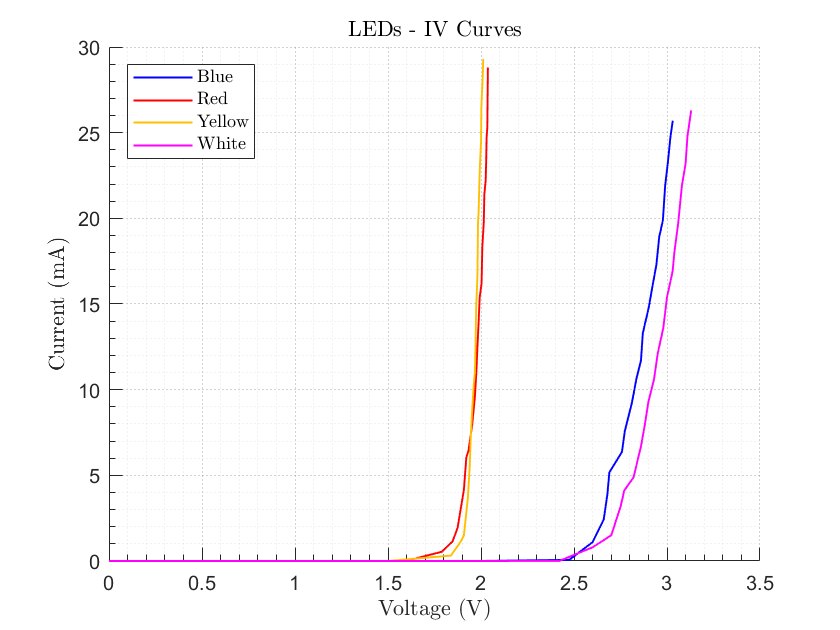

exportgraphics(f, 'C:\Users\glzdi\Documents\OpticsAndCV\PySciDevVS\src\Research\NonLinearFiberOptics\matlab\Data\IVCurves.pdf')